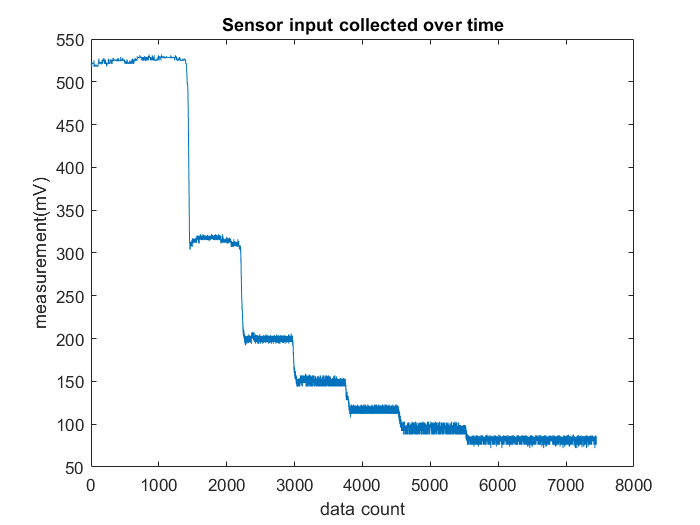

% plot raw sensor readings collected over time
figure(1)
load('calibrating_workspace_final.mat', "data")
plot(data)
xlabel("data count")
ylabel("measurement(mV)")
title("Sensor input collected over time")


% taking average of 300 data points at each distance
data_amount = 300;
rawV1 = mean(rmoutliers(data(500:500+data_amount),"mean"));
rawV2 = mean(rmoutliers(data(1600:1600+data_amount),"mean"));
rawV3 = mean(rmoutliers(data(2500:2500+data_amount),"mean"));
rawV4 = mean(rmoutliers(data(3200:3200+data_amount),"mean"));
rawV5 = mean(rmoutliers(data(4000:4000+data_amount),"mean"));
rawV6 = mean(rmoutliers(data(5000:5000+data_amount),"mean"));
rawV7 = mean(rmoutliers(data(5600:5600+data_amount),"mean"));

% ploting mearsurement vs distance
distance = linspace(20,140,7); % actual distances measured by hand
raw_data = [rawV1,rawV2,rawV3,rawV4,rawV5,rawV6,rawV7];


Best-ft curve that does not fit (polynomials don't work)

figure(3)
plot(raw_data,distance,"-o")
hold on
coefs = polyfit(raw_data,distance,2) % two degree polynomial

coefs =     0.0009   -0.7748  186.0272


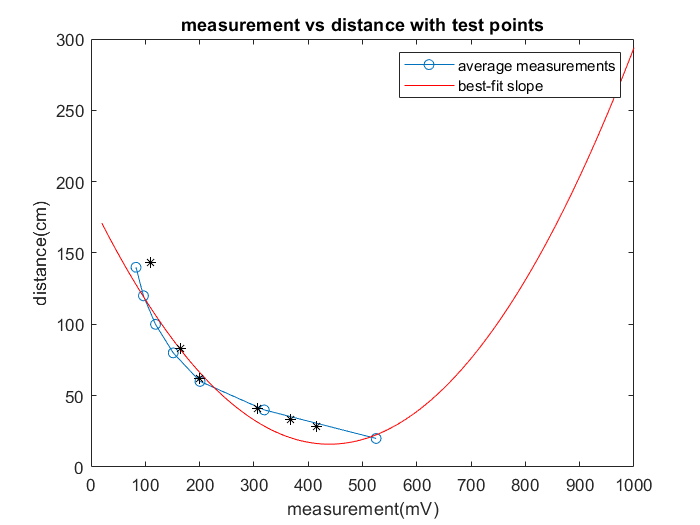

random_rawdata = linspace(20,1000,500);
calc_distance = polyval(coefs, random_rawdata);
plot(random_rawdata, calc_distance,"r-")
ylabel("distance(cm)")
xlabel("measurement(mV)")
title("measurement vs distance with test points")
plot( test_data,test_distance,"k*")
legend("average measurements","best-fit slope")
hold off 

Second try on best fit curve using cftool -- natural log

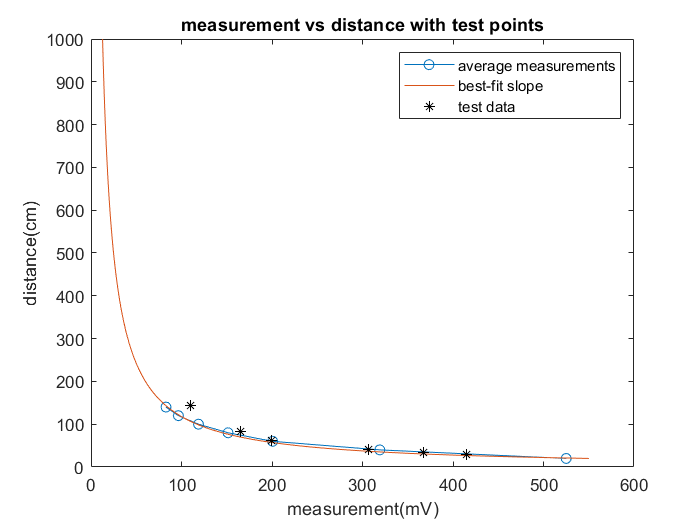

figure(4)
plot(rawData,distance,"-o")
hold on
% coefficients calculated using cftool (y = a * x ^ b)
a = 9800;
b = -0.9614;
calc_distance = a .* random_rawdata .^ b;
plot(calc_distance,random_rawdata)
ylabel("distance(cm)")
xlabel("measurement(mV)")
title("measurement vs distance with test points")
plot( test_data,test_distance,"k*")
legend("average measurements","best-fit slope","test data")

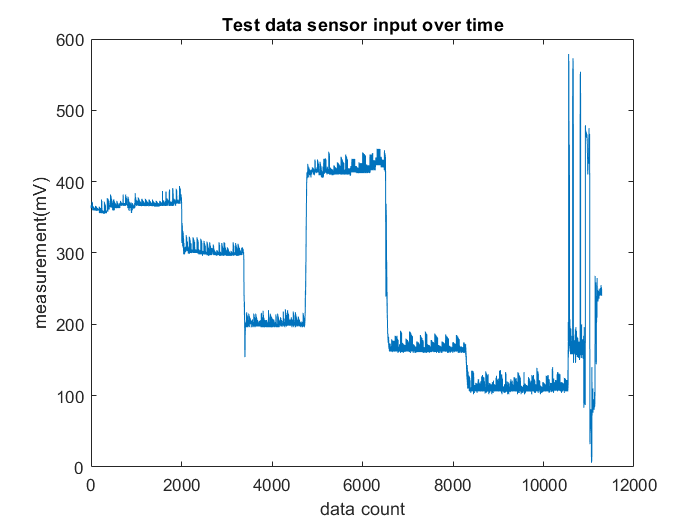

% plot testing data points using the same data cleaning method
figure(3)
plot(test)
test_data_amount = 300;
rawV1 = mean(rmoutliers(test(1000:1000+data_amount),"mean"));
rawV2 = mean(rmoutliers(test(2000:2000+data_amount),"mean"));
rawV3 = mean(rmoutliers(test(4000:4000+data_amount),"mean"));
rawV4 = mean(rmoutliers(test(5500:5500+data_amount),"mean"));
rawV5 = mean(rmoutliers(test(7000:7000+data_amount),"mean"));
rawV6 = mean(rmoutliers(test(8500:8500+data_amount),"mean"));
xlabel("data count")
ylabel("measurement(mV)")
title("Test data sensor input over time")

test_distance = [33, 41, 62, 28.5, 83, 143];
test_data = [rawV1,rawV2,rawV3,rawV4,rawV5,rawV6];